[images labels] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte',20000 ,0);
[trainimages trainlabels testimages testlabels]  = splitdata(images,labels, 0.8);

# Wavelet Study

[trainimages trainlabels testimages testlabels]  = splitdata(images,labels, 0.8);
[trainfeatures] = extractfeatureswithWaveletScattering(trainimages);

**Dimensionality Reduction**

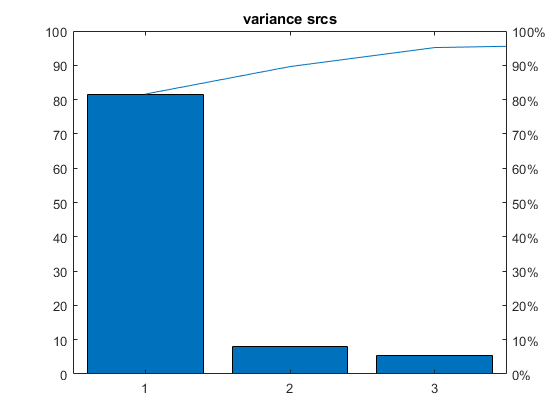

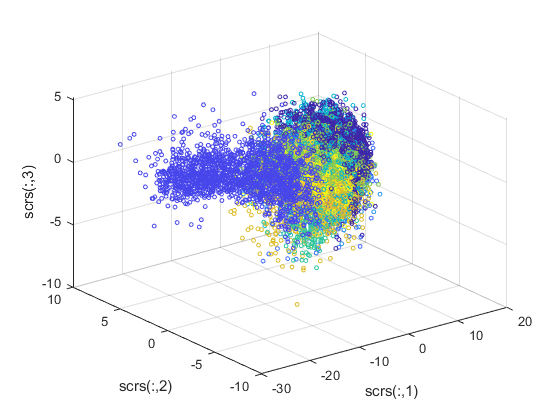

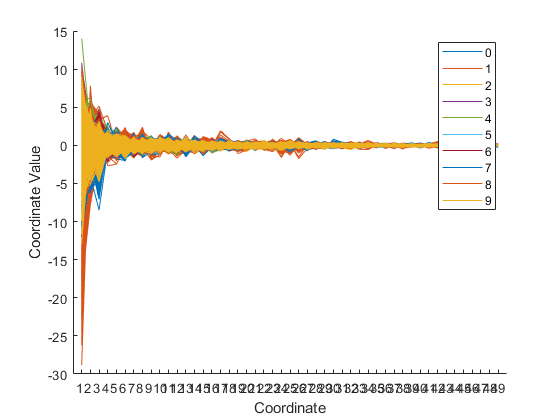

[trainfeaturesNorm, trainpcs, trainscrs] = study_of_data(trainfeatures, trainlabels);


for i = [2 5 10 50]
    [maxModel] = classification_learner(trainscrs, trainlabels,i);
    study_of_model(maxModel,trainscrs,trainlabels)
end

accuracy = 0.4782

    "FinetreeModel"



accuracy = 0.4260

    "MediumtreeModel"



accuracy = 0.3145

    "CoarsetreeModel"



accuracy = 0.7252

    "LinearDiscriminant"



accuracy = 0.7776

    "QuadraticDiscriminant"



accuracy = 0.6628

    "KernelNaiveBayes"



accuracy = 0.6832

    "GaussianNaiveBayes"



accuracy = 0.7582

    "LinearSVM"



accuracy = 0.7955

    "QuadraticSVM"



accuracy = 0.7891

    "CubicSVM"



accuracy = 0.1141

    "FineGuassianSVM"



accuracy = 0.7911

    "MediumGuassianSVM"



accuracy = 0.7334

    "CoarseGaussianSVM"



accuracy = 0.6193

    "MediumKNN"



accuracy = 0.6558

    "CosineKNN"



accuracy = 0.6171

    "CubicKNN"



accuracy = 0.6234

    "WeightedKNN"



accuracy = 0.4438

    "BoostedTrees"



accuracy = 0.5972

    "BaggedTrees"



accuracy = 0.7020

    "SubspaceDiscriminant"



accuracy = 0.6408

    "SubspaceKNN"



accuracy = 0.4405

    "RUSBoostedTrees"



Error using classreg.learning.classif/CompactClassificationEnsemble/predict
Too many output arguments.

Error in Practica2>study_of_model (line 207)
    [predictlabels,score,~,~] = predict(model,features);



[trainimages trainlabels testimages testlabels]  = splitdata(images,labels, 0.8);
[trainfeatures1] = extractfeatureswithWaveletScattering(trainimages);
[trainfeatures2] = extractfeatureswithKMeans(trainimages);
[trainfeatures3] = geometricpropieties(trainimages);
[trainfeatures4] = extractfeatureswithHOG(trainimages);
[trainfeatures5] = extractfeatureswithfourier_with_holes(trainimages);
listaFeatures = [trainfeatures1 trainfeatures2 trainfeatures3 trainfeatures4 trainfeatures5]

for i=listaFeatures
    study_of_model
end
[~, ~, trainscrs] = study_of_data(trainfeatures, trainlabels);





classification_learner(trainscrs, trainlabels,7);

accuracy = 0.4807

    "FinetreeModel"



accuracy = 0.4207

    "MediumtreeModel"



accuracy = 0.3126

    "CoarsetreeModel"



accuracy = 0.7202

    "LinearDiscriminant"



accuracy = 0.7879

    "QuadraticDiscriminant"



accuracy = 0.6742

    "KernelNaiveBayes"



accuracy = 0.6836

    "GaussianNaiveBayes"



accuracy = 0.7626

    "LinearSVM"



accuracy = 0.8110

    "QuadraticSVM"



accuracy = 0.8064

    "CubicSVM"



accuracy = 0.1139

    "FineGuassianSVM"



accuracy = 0.8059

    "MediumGuassianSVM"



accuracy = 0.7497

    "CoarseGaussianSVM"



accuracy = 0.6414

    "MediumKNN"



accuracy = 0.6710

    "CosineKNN"



accuracy = 0.6448

    "CubicKNN"



accuracy = 0.6514

    "WeightedKNN"



accuracy = 0.4325

    "BoostedTrees"



accuracy = 0.6216

    "BaggedTrees"



accuracy = 0.7023

    "SubspaceDiscriminant"



accuracy = 0.6534

    "SubspaceKNN"



accuracy = 0.4306

    "RUSBoostedTrees"



# Multiclass classifications

function [maxModel] = classification_learner(features, labels,k_fold)
    maxAcc = 0;
    FinetreeModel = fitctree(features,labels,"SplitCriterion","gdi","MaxNumSplits",100, 'Surrogate', 'off');
    [accuracy] = accuracy_result(FinetreeModel, features, labels,k_fold)
    display("FinetreeModel")
    if accuracy > maxAcc 
        maxModel = FinetreeModel;
    end
    
    MediumtreeModel = fitctree(features,labels,"SplitCriterion","gdi","MaxNumSplits",20, 'Surrogate', 'off');
    [accuracy] = accuracy_result(MediumtreeModel, features, labels,k_fold)
    display("MediumtreeModel")
    if accuracy > maxAcc 
        maxModel = FinetreeModel;
    end
    
    CoarsetreeModel = fitctree(features,labels,"SplitCriterion","gdi","MaxNumSplits",4, 'Surrogate', 'off');
    [accuracy] = accuracy_result(CoarsetreeModel, features, labels,k_fold)
    display("CoarsetreeModel")
    if accuracy > maxAcc 
        maxModel = FinetreeModel;
    end
    
    LinearDiscriminant =  fitcdiscr(features,labels,"DiscrimType","linear" , 'Gamma', 0, 'FillCoeffs', 'off');
    [accuracy] = accuracy_result(LinearDiscriminant, features, labels,k_fold)
    display("LinearDiscriminant")
    if accuracy > maxAcc 
        maxModel = LinearDiscriminant;
    end
    
    QuadraticDiscriminant = fitcdiscr(features,labels,"DiscrimType","quadratic", 'FillCoeffs', 'off');
    [accuracy] = accuracy_result(QuadraticDiscriminant, features, labels,k_fold)
    display("QuadraticDiscriminant")
    if accuracy > maxAcc 
        maxModel = QuadraticDiscriminant;
    end
    
    KernelNaiveBayes = fitcnb(features,labels,"DistributionNames",repmat({'Kernel'}, 1, size(features,2)), 'Kernel', 'Normal', 'Support', 'Unbounded');
    [accuracy] = accuracy_result(KernelNaiveBayes, features, labels,k_fold)
    display("KernelNaiveBayes")
    if accuracy > maxAcc 
        maxModel = KernelNaiveBayes;
    end
    
    GaussianNaiveBayes = fitcnb(features,labels,"DistributionNames",repmat({'Normal'}, 1, size(features,2)));
    [accuracy] = accuracy_result(GaussianNaiveBayes, features, labels,k_fold)
    display("GaussianNaiveBayes")
    if accuracy > maxAcc 
        maxModel = GaussianNaiveBayes;
    end
    
    t = templateSVM("KernelFunction","polynomial","PolynomialOrder",1,"KernelScale","auto","BoxConstraint",1,"Standardize",true);
    LinearSVM = fitcecoc(features,labels,"Learners",t, 'Coding', 'onevsone');
    [accuracy] = accuracy_result(LinearSVM, features, labels,k_fold)
    display("LinearSVM")
    if accuracy > maxAcc 
        maxModel = LinearSVM;
    end
    
    t = templateSVM("KernelFunction","polynomial","PolynomialOrder",2,"KernelScale","auto","BoxConstraint",1,"Standardize",true);
    QuadraticSVM = fitcecoc(features,labels,"Learners",t, 'Coding', 'onevsone');
    [accuracy] = accuracy_result(QuadraticSVM, features, labels,k_fold)
    display("QuadraticSVM")
    if accuracy > maxAcc 
        maxModel = QuadraticSVM;
    end
    
    t = templateSVM("KernelFunction","polynomial","PolynomialOrder",3,"KernelScale","auto","BoxConstraint",1,"Standardize",true);
    CubicSVM = fitcecoc(features,labels,"Learners",t, 'Coding', 'onevsone');
    [accuracy] = accuracy_result(CubicSVM, features, labels,k_fold)
    display("CubicSVM")
    if accuracy > maxAcc 
        maxModel = CubicSVM;
    end
    
    t = templateSVM("KernelFunction","gaussian", "KernelScale",1.8,"BoxConstraint",1,"Standardize",true);
    FineGuassianSVM = fitcecoc(features,labels,"Learners",t, 'Coding', 'onevsone');
    [accuracy] = accuracy_result(FineGuassianSVM, features, labels,k_fold)
    display("FineGuassianSVM")
    if accuracy > maxAcc 
        maxModel = FineGuassianSVM;
    end
    
    t = templateSVM("KernelFunction","gaussian", "KernelScale",7,"BoxConstraint",1,"Standardize",true);
    MediumGuassianSVM = fitcecoc(features,labels,"Learners",t,'Coding', 'onevsone');
    [accuracy] = accuracy_result(MediumGuassianSVM, features, labels,k_fold)
    display("MediumGuassianSVM")
    if accuracy > maxAcc 
        maxModel = MediumGuassianSVM;
    end
    
    t = templateSVM("KernelFunction","gaussian", "KernelScale",28,"BoxConstraint",1,"Standardize",true);
    CoarseGaussianSVM = fitcecoc(features,labels,"Learners",t,'Coding', 'onevsone');
    [accuracy] = accuracy_result(CoarseGaussianSVM, features, labels,k_fold)
    display("CoarseGaussianSVM")
    if accuracy > maxAcc 
        maxModel = CoarseGaussianSVM;
    end
    
    MediumKNN = fitcknn(features, labels,"NumNeighbors",10,"Distance","euclidean","DistanceWeight","equal","Standardize",true);
    [accuracy] = accuracy_result(MediumKNN, features, labels,k_fold)
    display("MediumKNN")
    if accuracy > maxAcc 
        maxModel = MediumKNN;
    end
    
    CosineKNN = fitcknn(features, labels,"NumNeighbors",10,"Distance","cosine","DistanceWeight","equal","Standardize",true);
    [accuracy] = accuracy_result(CosineKNN, features, labels,k_fold)
    display("CosineKNN")
    if accuracy > maxAcc 
        maxModel = CosineKNN;
    end
    
    CubicKNN = fitcknn(features, labels,"NumNeighbors",10,"Distance","minkowski","DistanceWeight","equal","Standardize",true);
    [accuracy] = accuracy_result(CubicKNN, features, labels,k_fold)
    display("CubicKNN")
    if accuracy > maxAcc 
        maxModel = CubicKNN;
    end
    
    WeightedKNN = fitcknn(features, labels,"NumNeighbors",10,"Distance","euclidean","DistanceWeight","inverse","Standardize",true);
    [accuracy] = accuracy_result(WeightedKNN, features, labels,k_fold)
    display("WeightedKNN")
    if accuracy > maxAcc 
        maxModel = WeightedKNN;
    end
    
    t = templateTree("MaxNumSplits" ,20);
    BoostedTrees = fitcensemble(features, labels, "Method","AdaBoostM2","Learners",t, "NumLearningCycles",30,"LearnRate",0.1);
    [accuracy] = accuracy_result(BoostedTrees, features, labels,k_fold)
    display("BoostedTrees")
    if accuracy > maxAcc 
        maxModel = BoostedTrees;
    end
    
    t = templateTree("MaxNumSplits" ,15999);
    BaggedTrees = fitcensemble(features, labels, "Method","Bag","Learners",t, "NumLearningCycles",30);
    [accuracy] = accuracy_result(BaggedTrees, features, labels,k_fold)
    display("BaggedTrees")
    if accuracy > maxAcc 
        maxModel = BaggedTrees;
    end
    
    SubspaceDiscriminant= fitcensemble(features, labels, "Method","Subspace", "Learners","discriminant", "NumLearningCycles",30, 'NPredToSample', max(1, min(25, size(labels,1) - 1)));
    [accuracy] = accuracy_result(SubspaceDiscriminant, features, labels,k_fold)
    display("SubspaceDiscriminant")
    if accuracy > maxAcc 
        maxModel = SubspaceDiscriminant;
    end
    
    SubspaceKNN = fitcensemble(features, labels, "Method","Subspace", "Learners","knn", "NumLearningCycles",30, 'NPredToSample', max(1, min(25, size(labels,1) - 1)));
    [accuracy] = accuracy_result(SubspaceKNN, features, labels,k_fold)
    display("SubspaceKNN")
    if accuracy > maxAcc 
        maxModel = SubspaceKNN;
    end
    
    t = templateTree("MaxNumSplits" ,20);
    RUSBoostedTrees = fitcensemble(features, labels, "Method","RUSBoost","Learners",t, "NumLearningCycles",30,"LearnRate",0.1);
    [accuracy] = accuracy_result(RUSBoostedTrees, features, labels,k_fold)
    display("RUSBoostedTrees")
    if accuracy > maxAcc 
        maxModel = RUSBoostedTrees;
    end
    
end

# Split data

function [trainimages trainlabels testimages testlabels]  = splitdata(images,labels, k)
    cv = cvpartition(size(images,3),'HoldOut',k);
    idx = cv.test;
    trainimages = images(:,:,idx);
    trainlabels = labels(idx);
    testimages = images(:,:,~idx);
    testlabels = labels(~idx);
end

# Study of model

function [] = study_of_model(model, features, labels)
    [predictlabels,score,~,~] = predict(model,features);
    confusionchart(labels,predictlabels);
    accuracy = nnz(labels ~= predictlabels)/length(labels)
    ClassNames = int2str(model.ClassNames);
    figure;
    for i = 1:10
        [X,Y,T,AUC,OPTROCPT] = perfcurve(labels,score(:,i),ClassNames(i));
        if (i ==2)
            hold on;
        end
        plot(X,Y);
        text(max(OPTROCPT(1)),max(OPTROCPT(2)),ClassNames(i),'FontSize',10);
    end
    xlabel('False positive rate');
    ylabel('True positive rate');
    title('ROC Curve');
    legend(ClassNames);
    hold off;
end
function [accuracy] = accuracy_result(model, features, labels, k_fold)
    partitionedModel = crossval(model, 'KFold', k_fold);
    accuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
end

# Study of data

function [featuresNorm,  pcs, scrs] = study_of_data(features, labels)
    %normalize data in A, center de data and scale to have standard
    %deviation 1
    featuresNorm = normalize(features);
    %PCA pcs = principal components coefficients (Matrix changes of basis),
    %scrs = princiapl scores (featuresNorm*pcs)
    %matrix, pexp = percentage of total variance explained
    [pcs,scrs,~,~,pexp] = pca(featuresNorm);
    %Pareto 
    figure 
    H = pareto(pexp);
    title('variance srcs')
    %PCA scatter 3 first columns
    figure
    scatter3(scrs(:,1),scrs(:,2),scrs(:,3),9,labels);
    xlabel('scrs(:,1)');
    ylabel('scrs(:,2)');
    zlabel('scrs(:,3)');
    figure
    parallelcoords(scrs,"Group",labels);
end

# All points feature

function [features] = extractfeaturesallpoints(images)
    [D1, D2, nimages] = size(images);
    features = zeros(nimages, D1*D2);
    for i = 1:nimages
        im = images(:,:,i);
        features(i,:) = im(:);
    end
end


# Shape Context feature

function [features] = extractfeatureswithShapeContext_multicenters(images, centers, radi, nbins_r, nbins_theta)
    [n_centers ~] = size(centers);
    [~, ~, nimages] = size(images);
    features = zeros(nimages, nbins_r*nbins_theta*n_centers);
    for i = 1:nimages
        im = images(:,:,i);
        feature = zeros(1,nbins_r*nbins_theta*n_centers);
        for j = 1:n_centers
           feature_aux =  ShapeContext(im, centers(j,:), radi, nbins_r, nbins_theta);
           feature(((j-1)*nbins_r*nbins_theta)+1:(j*nbins_r*nbins_theta)) = feature_aux;
        end
        features(i,:) = feature;
    end
 end
 
function [feature] = ShapeContext(im, center, radi, nbins_r, nbins_theta)
    %Hago un resize de la imagen [200 200]
    [~, points] = gecontour(im);
    [D1 D2] = size(points);
    %Calculate euclidean distance
    distances = points-center;
    distances = sqrt((distances(:,1).^2)+(distances(:,2).^2));
    %calculate r_bin
    r_bin_edges = logspace(log10(1), log10(radi), nbins_r);
    r_bin = double(zeros(D1,1));
    for i=1:length(r_bin_edges)
        s = (distances<r_bin_edges(1,i));
        r_bin = r_bin + double(s);
    end
    
    %calculate angle between two points
    distance = points-center;
    angle = atan(distance(:,2)./distance(:,1));
    min_angle = min(angle);
    if (min_angle < 0)
        angle = (angle+abs(min(angle)));
    end
    angle = (angle*2*pi)./max(angle);
    
    %calculate theta_bins
    theta_bin_edge = linspace(0,2*pi,nbins_theta);
    theta_bin = double(zeros(D1,1));
    for i=1:length(theta_bin_edge)
        s = (angle<theta_bin_edge(1,i));
        theta_bin = theta_bin + double(s);
    end
    
    feature = double(zeros(1,nbins_r*nbins_theta));
    k = 1;
    for i = 1:nbins_r
       for j = 1:nbins_theta
           features_aux = (r_bin == i) & (theta_bin == j);
           feature(k)= sum(features_aux);
           k = k+1;
       end
    end
    
end
function [contour, points] = gecontour(im)
    %lo mismo que im = im -imclose(im) o cany; Hago un resize de la imagen [200
    %200]
    im = imbinarize(im);
    im = imresize(im, [200 200]);
    [D1 D2] = size(im);
    contour = logical(zeros(D1,D2));
    points = [];
    for i = 2:(D1-1)
        for j = 2:(D2-1)
            if ((~im(i,j-1) || ~im(i,j+1) || ~im(i+1,j) || ~im(i-1,j)) && im(i,j))
               contour(i,j) = true;
               points = [points; [i j]];
            end
        end
    end
end

# Fast-Fourier(Características de contorn) 

function [features] = extractfeatureswithfourier(images,Ndescriptors)
    [~, ~, nimages] = size(images);
    features = zeros(nimages, Ndescriptors);
    for i = 1:nimages
        im = images(:,:,i);
        features(i,:) = descriptor_fourier(im, Ndescriptors,false);
    end
end
function [features] = extractfeatureswithfourier_with_holes(images,Ndescriptors)
    [~, ~, nimages] = size(images);
    features = zeros(nimages, Ndescriptors);
    for i = 1:nimages
        im = images(:,:,i);
        [D1 D2] = size(features);
        descriptor = descriptor_fourier(im, Ndescriptors,true);
        [d1 d2] = size(descriptor);
        if D2 < d2
           features_aux = zeros(D1,d2);
           features_aux(:,1:D2) = features;
           features = features_aux;
        elseif (d2<D2)
           descriptor_aux = zeros(1,D2);
           descriptor_aux(1,1:d2) = descriptor;
           descriptor = descriptor_aux;
        end
        features(i,:) = descriptor;
    end
end

function [descriptor] = descriptor_fourier(im, Ndescriptors, forats)
    [d1 d2 d3] = size(im);
    im = imbinarize(im);
    im = imresize(im, [300 300]);
    % obtenim les coordenades del contorn
    [fila col] = find(im,1); % Busquem el primer píxel
    B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
    % centrem coordenades
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + 1i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:); %dupliquem l'ultim
        mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    descriptor=fft(s);
    % Obtenim els descriptros
       
    descriptor = descriptor(1:Ndescriptors);
    %log del resultat es opcional, absoluto porque la classificacion en
    %matlab no puede ser imaginario
    descriptor = log(abs(descriptor));
    descriptor = descriptor';
    if (~forats)
           return
    end
    
    
    %descriptor fourier forats
    im = imcomplement(im);
    mark=true(size(im));
    mark(2:end-1,2:end-1) = 0;
    dilc = imreconstruct(mark,im);
    res = ~dilc;
    im = xor(res,im);
    im = imcomplement(im);
    [BW, numberOfObject] = bwlabel(im);
    for i = 1:numberOfObject
        descriptors_aux = descriptor_fourier(double(BW == i), Ndescriptors, false);
        descriptor = [descriptor descriptors_aux];
    end
end


# HOG Features(Histogram of oriented gradients)

[https://es.mathworks.com/help/supportpkg/android/ref/digit-classification-using-hog-features-on-mnist-database.html](https://es.mathworks.com/help/supportpkg/android/ref/digit-classification-using-hog-features-on-mnist-database.html)

function [features] = extractfeatureswithHOG(images, cellSize)
    im = images(:,:,1);
    im = imbinarize(im);
    im = imresize(im, [28 28]);
    hogFeatureSize = length(extractHOGFeatures(im, 'CellSize', cellSize));
    [~, ~, nimages] = size(images);
    features = zeros(nimages, hogFeatureSize);
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        im = imresize(im, [28 28]);
        [feature , image] = extractHOGFeatures(im, 'CellSize', cellSize);
        
        plot(image);
        features(i,:) = feature;
    end
end

# Wavelet Scattering

[https://es.mathworks.com/help/wavelet/examples/digit-classification-with-wavelet-scattering.html](https://es.mathworks.com/help/wavelet/examples/digit-classification-with-wavelet-scattering.html)

function [features] = extractfeatureswithWaveletScattering(images)
    sf = waveletScattering2('ImageSize', [28 28]);
    [~, ~, nimages] = size(images);
    for i = 1:nimages
        im = imresize(images(:,:,i),[28 28]);
        if (i == 1)
           feature  = helperScatImages(sf,im);
           l = length(feature);
           features = zeros(nimages, l);
           features(1,:) = feature';
        else
            features(i,:)  = helperScatImages(sf,im)';
        end
    end
end
function features = helperScatImages(sf,x)
% This function is only to support examples in the Wavelet Toolbox.
% It may change or be removed in a future release.
% Copyright 2018 MathWorks
    smat = featureMatrix(sf,x,'transform','log');
    features = mean(mean(smat,2),3);
end

# Number of Corners (Harris Corner Detector)

function [features] = extractfeatureswithHarrisCorner(images)
    [~, ~, nimages] = size(images);
    features = zeros(nimages, 1);
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        corners =  detectHarrisFeatures(im);
        features(i,:) = length(corners);
    end    
end

# Propietats geometricas

function [features] = geometricpropieties(images)
    [~, ~, nimages] = size(images);
    features = zeros(nimages,2);
    %Area y Area de les concavitats de la figura
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        features(i,1) = sum(im(:));
        CH = bwconvhull(im);
        feature = sum(CH(:));
        features(i,2) = sum(feature)- features(i,1);
    end
    %Numero de forats
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        im = imcomplement(im);
        mark=true(size(im));
        mark(2:end-1,2:end-1) = 0;
        dilc = imreconstruct(mark,im);
        res = ~dilc;
        im = xor(res,im);
        im = imcomplement(im);
        [~, numberOfObject] = bwlabel(im);
        features(i,3) = numberOfObject;
    end
end

# K-Means

function [features] = extractfeatureswithKMeans(images)
    NClusters = 8;
    [MAXFILA, MAXCOL, nimages] = size(images);
    features = zeros(nimages, NClusters*2);
    [A,B] = meshgrid((1:20),(1:20));
    c=cat(2,A',B');
    d=reshape(c,[],2);
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        %im
        %figure,imshow(im)
        %label = double(reshape(im,MAXFILA*MAXCOL,1));
        label = reshape(im,MAXFILA*MAXCOL,1);
        
        d1 = d(:,1);
        d2 = d(:,2);
        d1 = d1(label == 1);
        d2 = d2(label == 1);
        aux = [d1 d2];
        [~, clusterC] = kmeans(aux,NClusters);
        %[cluster_idx, clusterC] = kmeans(aux,NClusters);
        %label(label == 1) = cluster_idx;
        %eti=reshape(label,MAXFILA,MAXCOL);
        %figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')
        centreAux = sortrows(clusterC,1);
        %feature = zeros(1,length(centreAux));
        %for cont = 1:centreAux
        %    feature(cont) = norm(centreAux(cont,:));
        %end
        %features(i,:) = sort(feature);
        features(i,:) = reshape(centreAux,[],1);
    end
end


function [features] = extractfeatureswithKMeansOrdered(images,trainlabels)
    NClusters = 8;
    [MAXFILA, MAXCOL, nimages] = size(images);
    features = zeros(nimages, NClusters*2);
    [A,B] = meshgrid((1:20),(1:20));
    c=cat(2,A',B');
    d=reshape(c,[],2);
    ordenCero = [6.16666666666667,9.33333333333333;10.6153846153846,5.23076923076923;16.3333333333333,4.58333333333333;19.0714285714286,7.14285714285714;17.2000000000000,12.2000000000000;12.3529411764706,17.1764705882353;6.66666666666667,17.6000000000000;3.21739130434783,13.6521739130435];  
    ordenUno = [2.87500000000000,16.1250000000000;5.25000000000000,14.7500000000000;7.28571428571429,13;9.62500000000000,12.2500000000000;12.3000000000000,10.4000000000000;14.5555555555556,8.66666666666667;17,7.75000000000000;19.1250000000000,6.87500000000000];
    ordenDos = [5.88888888888889,8.66666666666667;3.68750000000000,13.7500000000000;8.09090909090909,15.3636363636364;11.8333333333333,12.8750000000000;12.8000000000000,7.20000000000000;16.8888888888889,4;16.2142857142857,9.35714285714286;14.6363636363636,17.7272727272727];
    ordenTres = [3.88235294117647,8.94117647058824;3.33333333333333,14.1904761904762;6.40000000000000,16.5500000000000;11.1904761904762,13.6666666666667;11.1666666666667,8.55555555555556;17,13.5000000000000;19,9;18.6875000000000,4.06250000000000];
    ordenCuatro = [5,1.50000000000000;8.28571428571429,1.42857142857143;12.3636363636364,2.81818181818182;11.7272727272727,8.63636363636364;10.2857142857143,15;5.07692307692308,17.2307692307692;14.4444444444444,14.8888888888889;18.7000000000000,14.8000000000000];
    ordenCinco = [2.50000000000000,18;3.70588235294118,13;4.41176470588235,7.70588235294118;7.80000000000000,9.20000000000000;11.1111111111111,12.4444444444444;14.6250000000000,14.6875000000000;17.2000000000000,10.7333333333333;19.4000000000000,5.93333333333333];
    ordenSeis = [2.23076923076923,11.5384615384615;6.16666666666667,8.41666666666667;10,6.84615384615385;14.5714285714286,5.14285714285714;16.7333333333333,8.80000000000000;15.4545454545455,12.7272727272727;10.5000000000000,16.0500000000000;11.8461538461538,11.3076923076923];
    ordenSiete = [8.47619047619048,5.61904761904762;5.75000000000000,10.9166666666667;5.50000000000000,16;9.08333333333333,15.3333333333333;11.8750000000000,12.8750000000000;14.6000000000000,11.3000000000000;17.2857142857143,9.14285714285714;19.5000000000000,7.50000000000000];
    ordenOcho = [5.84210526315790,9.47368421052632;10.7500000000000,9.62500000000000;14.5000000000000,6.80000000000000;18.5000000000000,5;18.8000000000000,8.80000000000000;14.4285714285714,11;8.76923076923077,13.6923076923077;4.42105263157895,15.8947368421053];
    ordenNueve = [5.72727272727273,15.2727272727273;4.50000000000000,11.5000000000000;6.66666666666667,8.33333333333333;10.6315789473684,5.52631578947368;11.8666666666667,10.6666666666667;9.20000000000000,13.6000000000000;15.5000000000000,11.5000000000000;19,11.5000000000000];
    
    for i = 1:nimages
        switch trainlabels(i)
            case 0
                orden = sqrt(sum(ordenCero.^2,2));
            case 1
                orden = sqrt(sum(ordenUno.^2,2));
            case 2
                orden = sqrt(sum(ordenDos.^2,2));
            case 3
                orden = sqrt(sum(ordenTres.^2,2));
            case 4
                orden = sqrt(sum(ordenCuatro.^2,2));
            case 5
                orden = sqrt(sum(ordenCinco.^2,2));
            case 6
                orden = sqrt(sum(ordenSeis.^2,2));
            case 7
                orden = sqrt(sum(ordenSiete.^2,2));
            case 8
                orden = sqrt(sum(ordenOcho.^2,2));
            case 9
                orden = sqrt(sum(ordenNueve.^2,2));
        end
        im = images(:,:,i);
        im = imbinarize(im);
        %im
        %figure,imshow(im)
        label = double(reshape(im,MAXFILA*MAXCOL,1));
        %label = reshape(im,MAXFILA*MAXCOL,1);
        
        d1 = d(:,1);
        d2 = d(:,2);
        d1 = d1(label == 1);
        d2 = d2(label == 1);
        aux = [d1 d2];
        [~, clusterC] = kmeans(aux,NClusters);
        %[cluster_idx, clusterC] = kmeans(aux,NClusters);
        %label(label == 1) = cluster_idx;
        %eti=reshape(label,MAXFILA,MAXCOL);
        %figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')
        
        pos = perms(1:NClusters);
        minPos = 1;
        minValor = Inf;
        for j=1:length(pos)
            clusterOrd = clusterC(pos(j,:),:);
            euclDist = sqrt(sum(clusterOrd.^2,2));
            mse = mean((orden-euclDist).^2);
            if minValor > mse
                minValor = mse;
                minPos = j;
            end
        end
        clusterC = clusterC(pos(minPos,:),:);
        %{
        s = (1:NClusters)';
        t = (1:.05:NClusters)';
        x = clusterC(:,1);
        y = clusterC(:,2);
        u = pchiptx(s,x,t);
        v = pchiptx(s,y,t);
        %clf reset
        plot(x,y,'.',u,v,'-');
        %}
        %features = clusterC;
        features(i,:) = reshape(clusterC,16,1);
        
    end
end